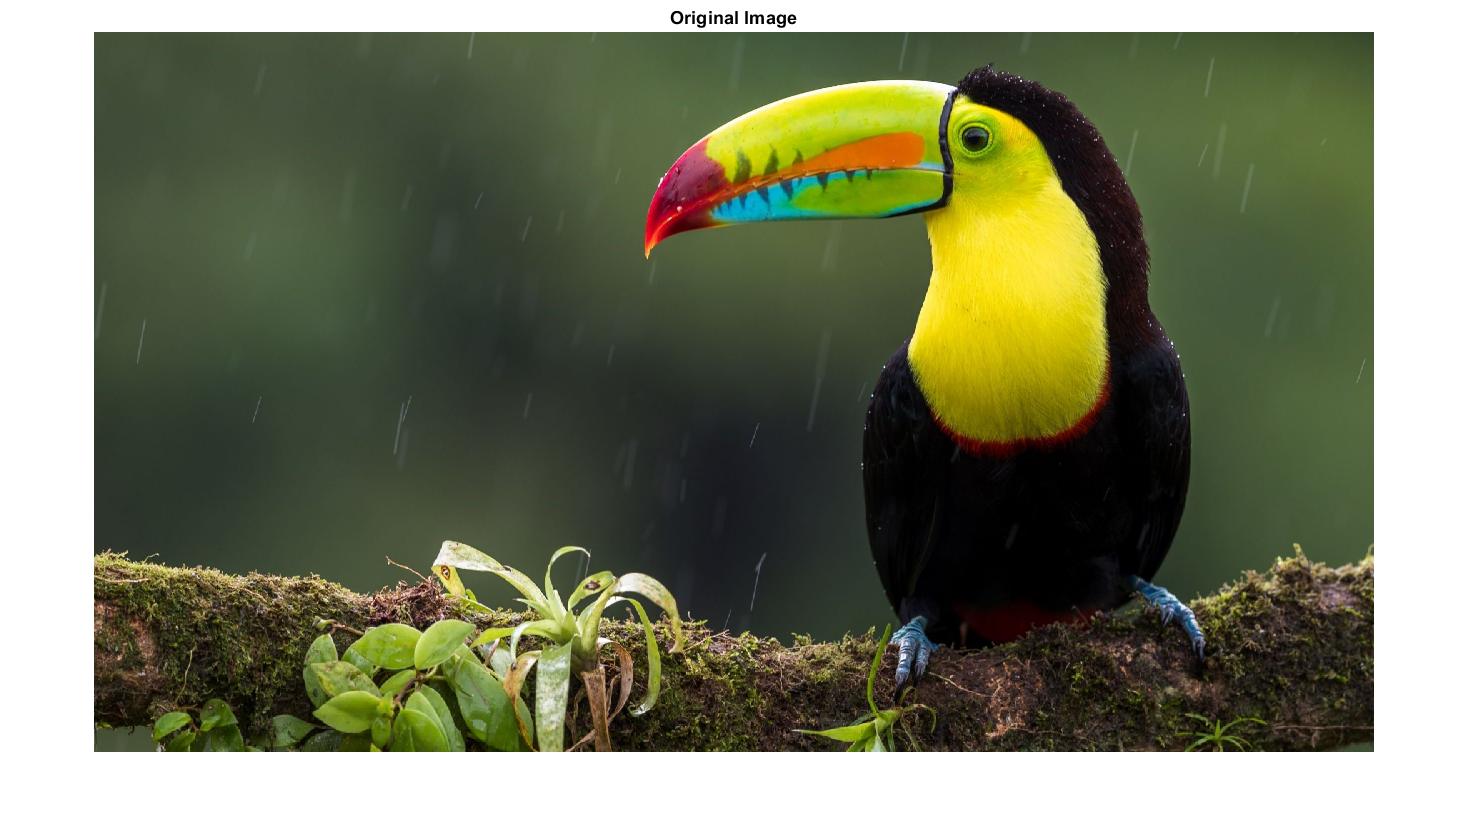

clear
clf

% Settings
partitionSize = 10;
hexFile = 'diverse-natural.hex';
shapeFile = 'circle.png';
imageFile = 'toucan.jpg';

im = imread(imageFile);
imshow(im);
title('Original Image');


outputHex = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'meanColorDistance');

Image has been resized. Resizing may result in loss of detail and image quality degradation.


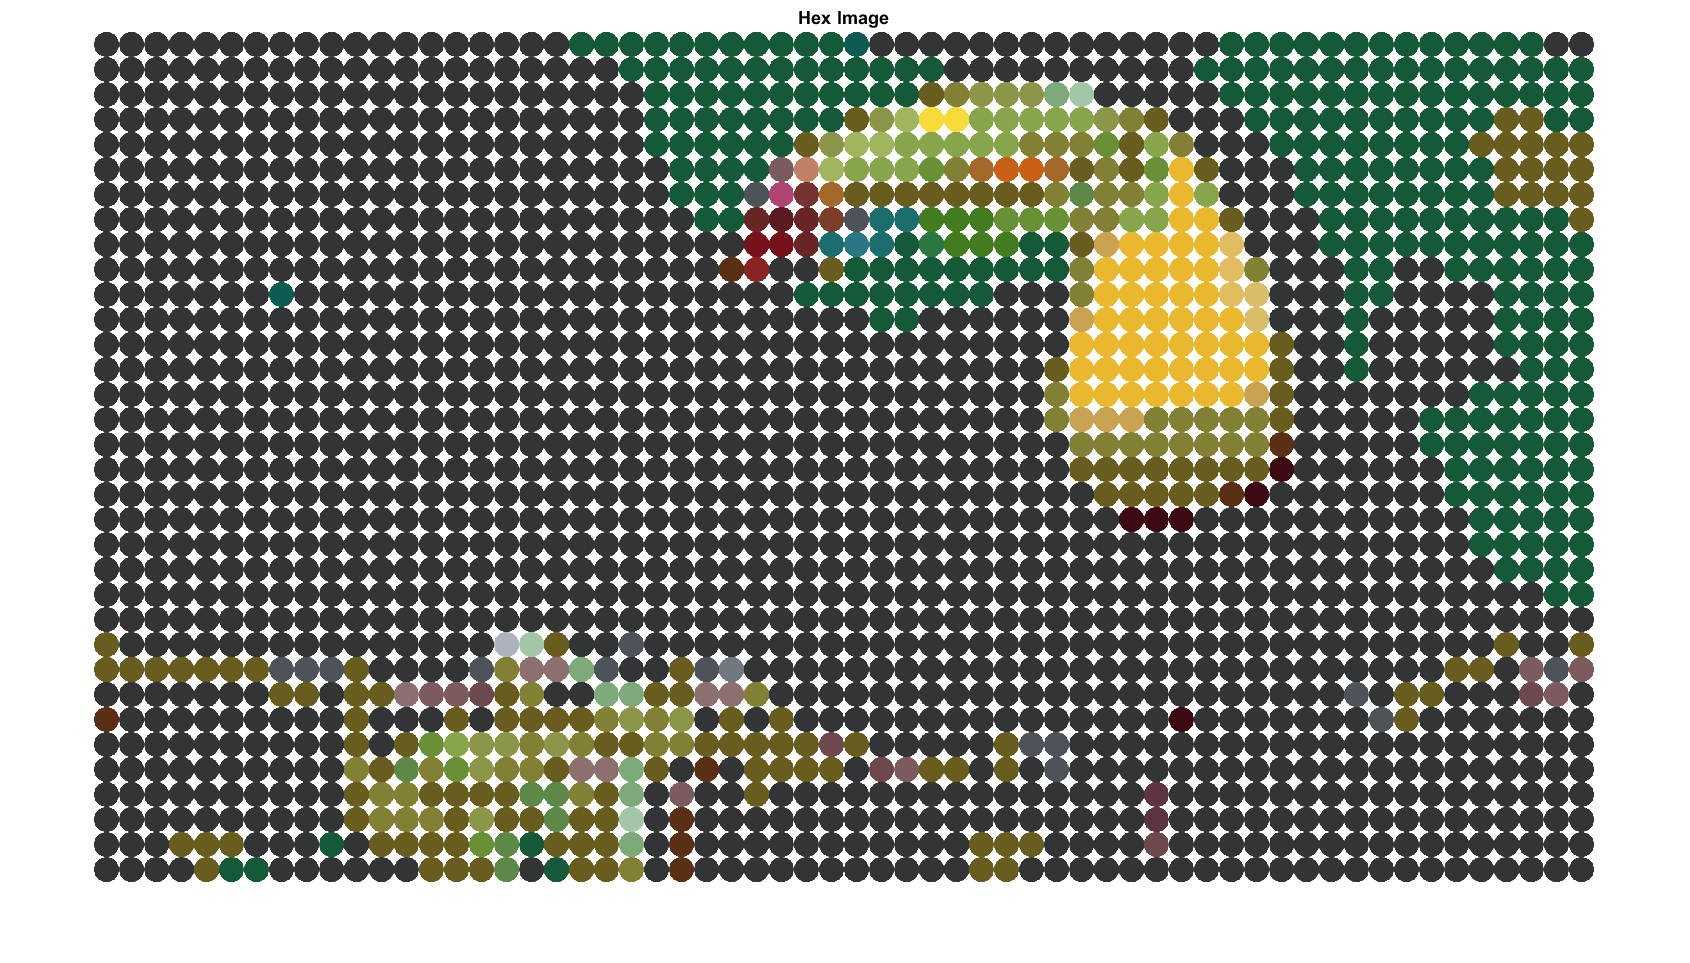

imshow(outputHex);
title('Hex Image');


outputReducedColor = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'globalReduction');

Image has been resized. Resizing may result in loss of detail and image quality degradation.


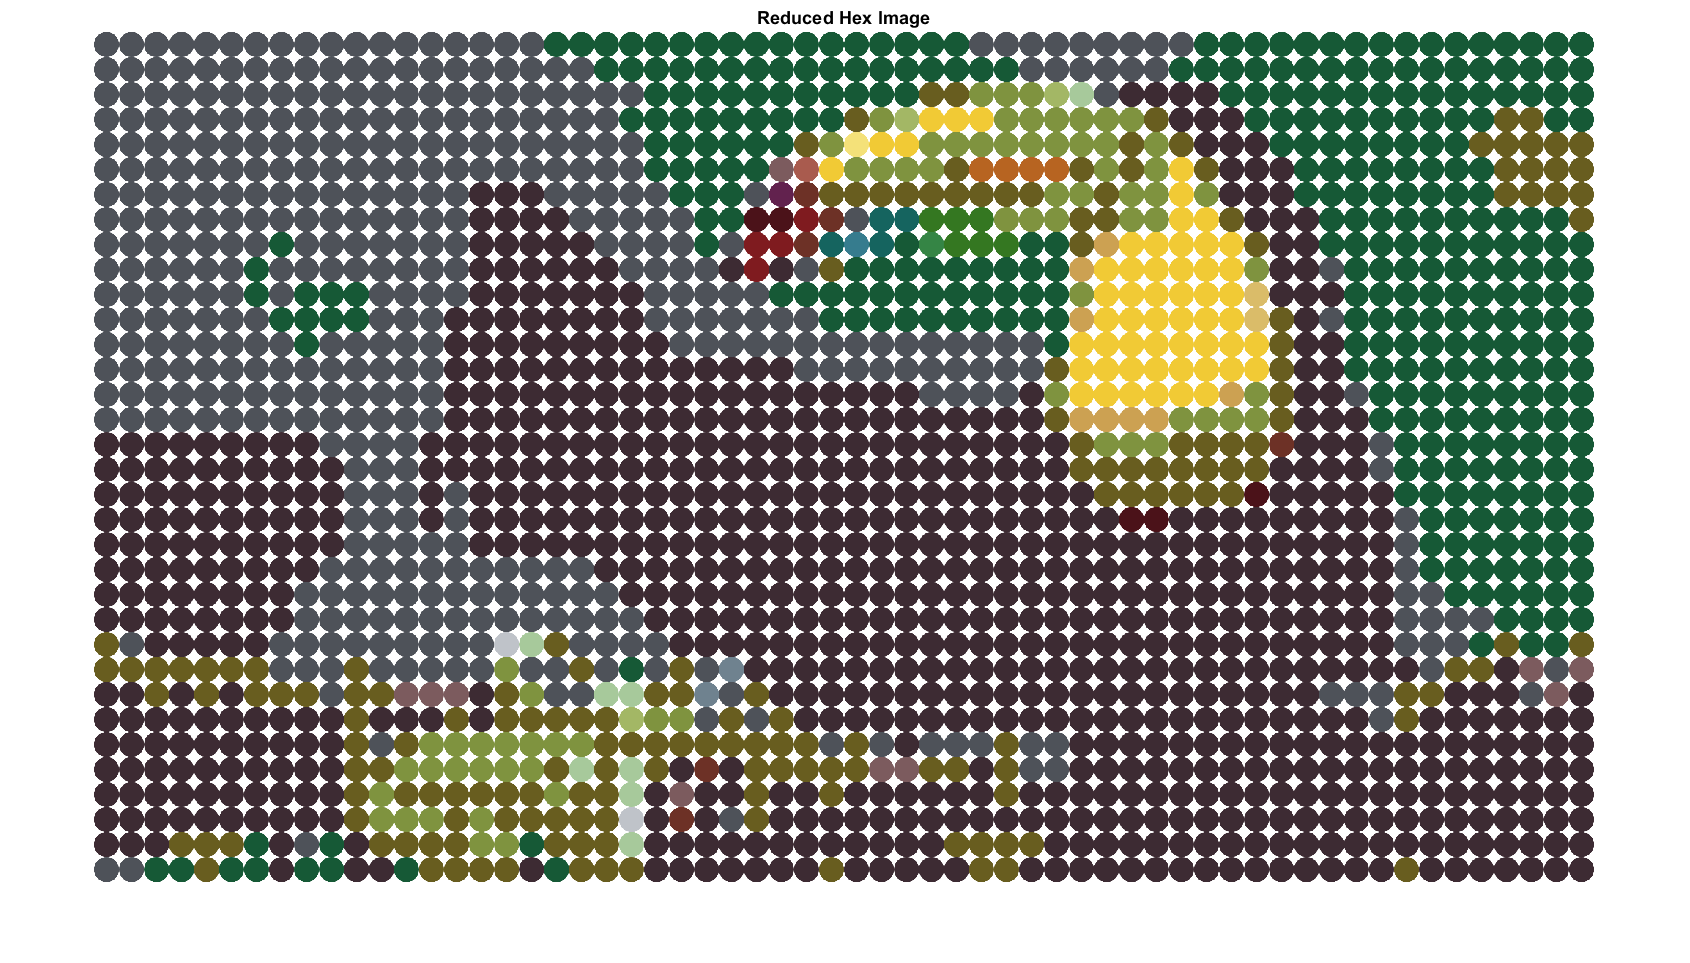

imshow(outputReducedColor);
title('Reduced Hex Image');


outputOGColor = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'imageColorDistance');

Image has been resized. Resizing may result in loss of detail and image quality degradation.


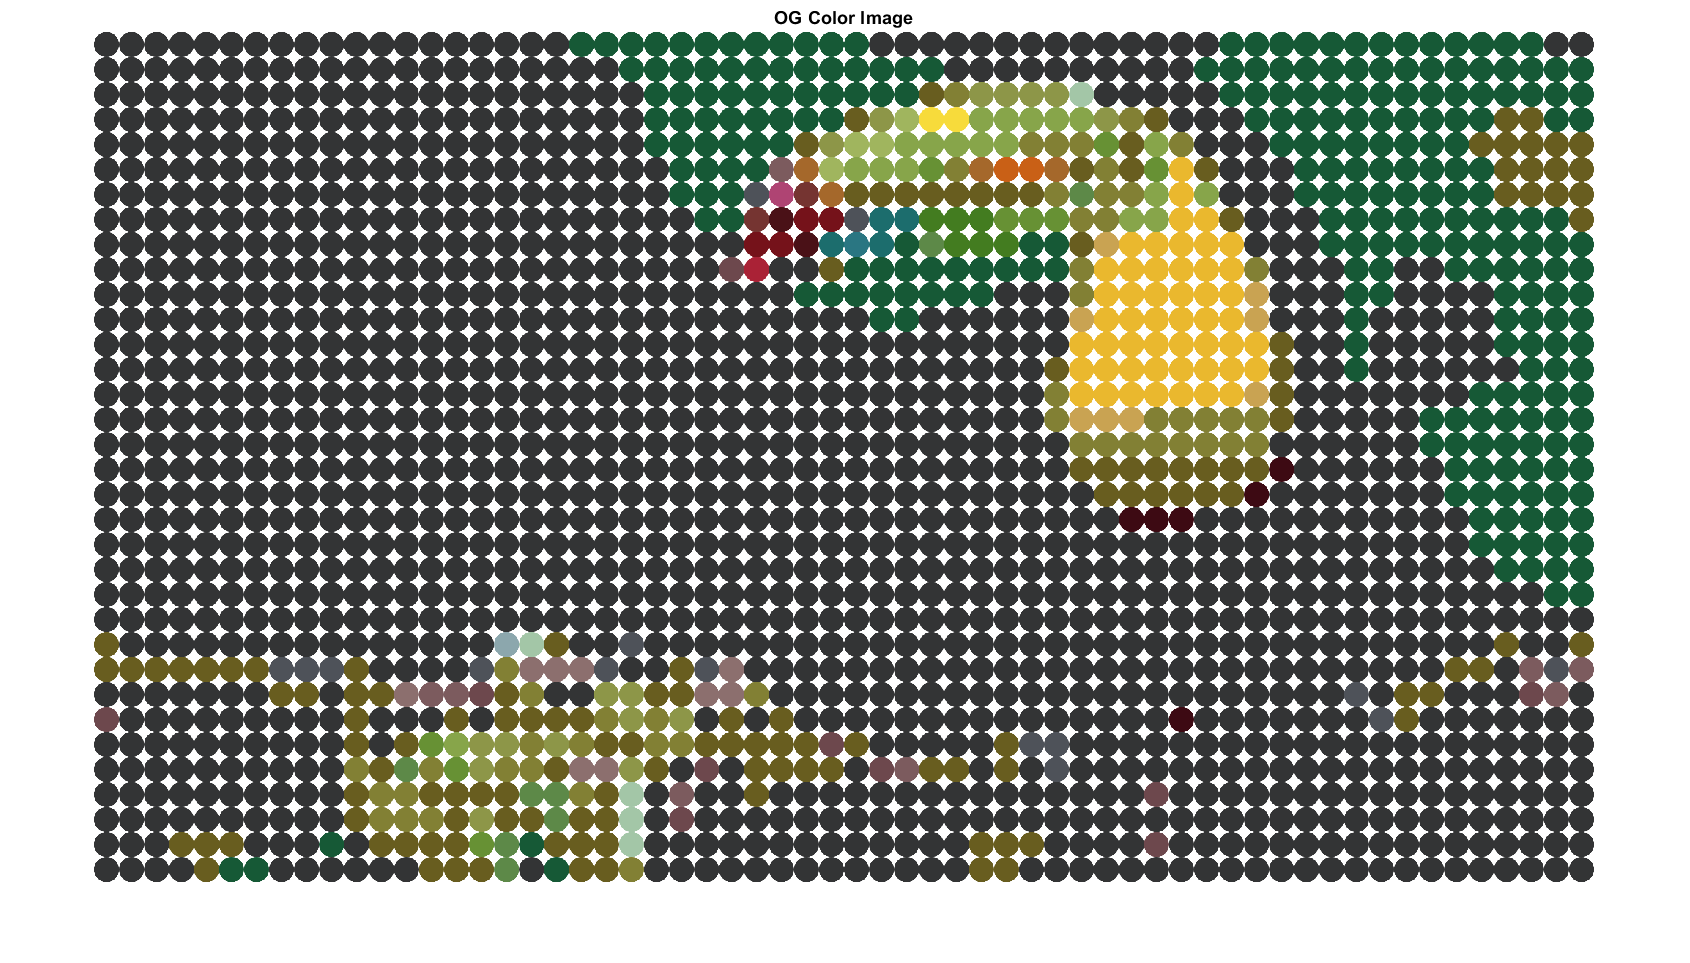

imshow(outputOGColor);
title('OG Color Image');

% Prepare for quality metrics

% Convert the images to double
load("xyz.mat");
im = im2double(im);
outputHex = im2double(outputHex);
outputReducedColor = im2double(outputReducedColor);
outputOGColor = im2double(outputOGColor);

% Determine the target dimensions
targetWidth = 1920;
targetHeight = size(im, 1) * targetWidth / size(im, 2);

% Resize the images using bicubic interpolation while maintaining aspect ratio
im = imresize(im, [targetHeight, targetWidth], 'bicubic');
outputHex = imresize(outputHex, [targetHeight, targetWidth], 'bicubic');
outputReducedColor = imresize(outputReducedColor, [targetHeight, targetWidth], 'bicubic');
outputOGColor = imresize(outputOGColor, [targetHeight, targetWidth], 'bicubic');

% SCIELAB
ppi = 141.21; % Lovisa's laptop
d = 500/25.4; % Viewing distance in inches
sampPerDeg = ppi * d * tan(pi/180);
whitepoint = [95.05, 100, 108.9];
format = 'xyz';

fullmetric = scielab(sampPerDeg, rgb2xyz(im), rgb2xyz(outputHex), whitepoint, format);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


mean(mean(fullmetric))

ans = 2.7079


fullmetric = scielab(sampPerDeg, rgb2xyz(im), rgb2xyz(outputReducedColor), whitepoint, format);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


mean(mean(fullmetric))

ans = 2.7132


fullmetric = scielab(sampPerDeg, rgb2xyz(im), rgb2xyz(outputOGColor), whitepoint, format);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


mean(mean(fullmetric))

ans = 2.7089

% Delta E

% Convert the images to the CIELAB color space
lab1 = rgb2lab(im);
outputHexLab = rgb2lab(outputHex);
outputReducedColorLab = rgb2lab(outputReducedColor);
outputOGColorLab = rgb2lab(outputOGColor);

% Calculate the color difference for each pixel
deltaE = sqrt(sum((lab1 - outputHexLab).^2, 3)); % Euclidean distance in Lab space
mean(deltaE(:))

ans = 30.9260

max(deltaE(:))

ans = 110.0815


deltaE = sqrt(sum((lab1 - outputReducedColorLab).^2, 3)); % Euclidean distance in Lab space
mean(deltaE(:))

ans = 32.0824

max(deltaE(:))

ans = 110.0875


deltaE = sqrt(sum((lab1 - outputOGColorLab).^2, 3)); % Euclidean distance in Lab space
mean(deltaE(:))

ans = 30.9314

max(deltaE(:))

ans = 110.3388

% SSIM

ssim(rgb2lab(outputHex),rgb2lab(im))

ans = 0.5160

ssim(rgb2lab(outputReducedColor), rgb2lab(im))

ans = 0.4962

ssim(rgb2lab(outputOGColor), rgb2lab(im))

ans = 0.5166